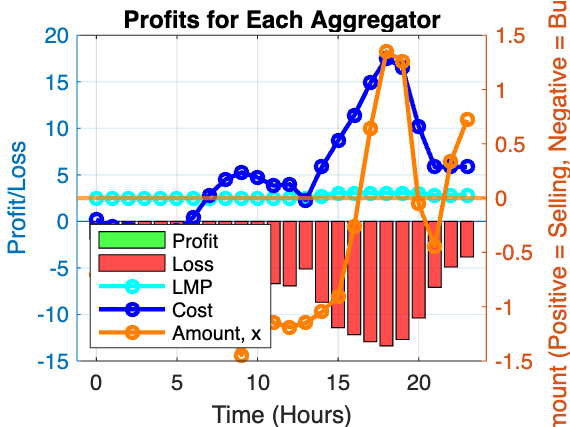

%load('Battery25_PV3.mat');
%load('Battery0_PV1.mat');
%load('Battery25_PV3_scenario2.mat');
cost1_vec = cost_vec1_PVscenario99;
cost2_vec = cost_vec2_PVscenario99;
cost3_vec = cost_vec3_PVscenario99;
cost4_vec = cost_vec4_PVscenario99;
cost5_vec = cost_vec5_PVscenario99;
t = 0:23;
clf;

visualizeTransactions(lmp1,cost1_vec,X_giv(:,1))

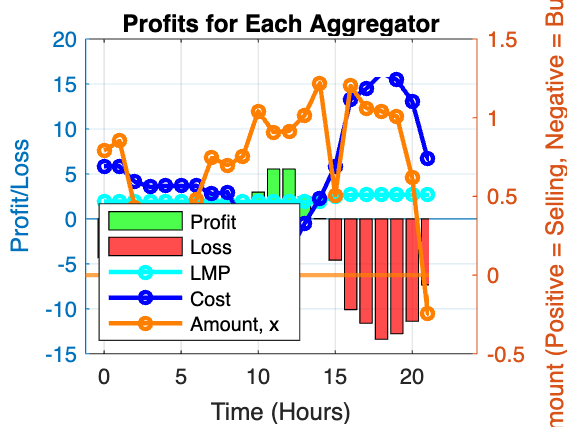

visualizeTransactions(lmp2,cost2_vec,X_giv(:,2))

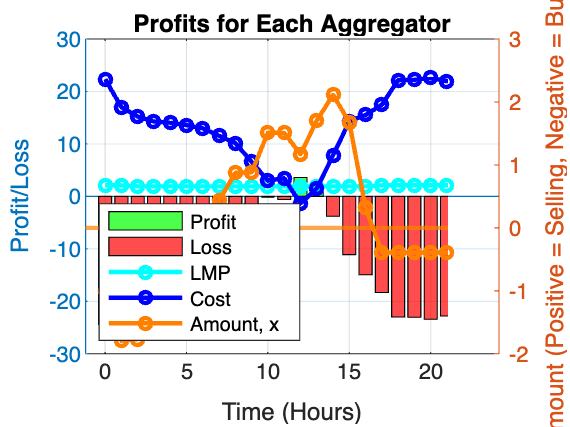

visualizeTransactions(lmp3,cost3_vec,X_giv(:,3))
visualizeTransactions(lmp4,cost4_vec,X_giv(:,4))

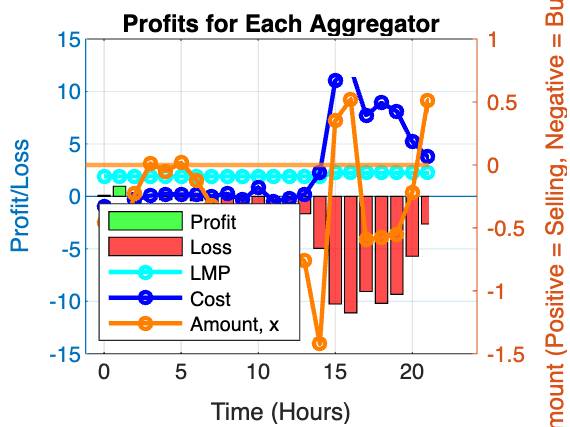

visualizeTransactions(lmp5,cost5_vec,X_giv(:,5))


function visualizeTransactions(price, cost, amount)
    % Compute profit/loss
    profit = price .* amount - cost;

    % Time axis (0 to 23 hours)
    time = 0:23;

    % Separate profit and loss for color coding
    profit_bar = max(profit, 0);  % Only positive (profit)
    loss_bar = min(profit, 0);    % Only negative (loss)

    % Create figure
    figure;
    yyaxis left
    bar(time, profit_bar, 'g', 'FaceAlpha', 0.7); % Green for profit
    hold on;
    bar(time, loss_bar, 'r', 'FaceAlpha', 0.7);   % Red for loss
    ylabel('Profit/Loss');
    hold on;
    plot(time,price,'c-o', 'LineWidth', 2, 'MarkerSize', 5);
    hold on;
    plot(time,cost,'b-o', 'LineWidth', 2, 'MarkerSize', 5);
    
    yyaxis right
    plot(time, amount, '-o', 'Color', [1, 0.5, 0], 'LineWidth', 2, 'MarkerSize', 5);
    ylabel('Amount (Positive = Selling, Negative = Buying)');
    hold on;
    yline(0, 'Color', [1, 0.5, 0], 'LineWidth', 2); % 'm' for magenta
    
    % Labels & Styling
    xlabel('Time (Hours)');
    title('Profits for Each Aggregator');
    legend('Profit', 'Loss','LMP', 'Cost','Amount, x', 'Location', 'southwest');
    grid on;
end
